clear;
clc;
close all;

% Script written by Jo Wayne Tan, jwt617, to produce plots for the
% CFD coursework. 04/12/2020.

## Question 1f

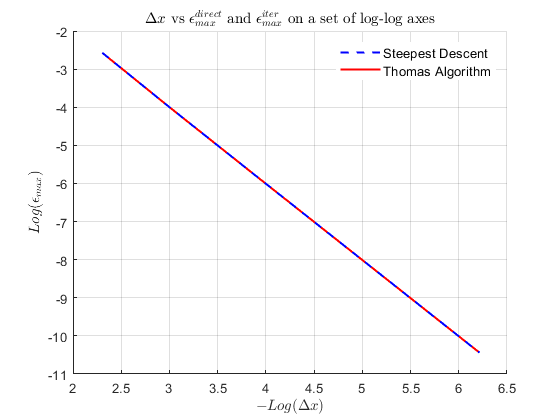

dx_1f = [0.1 0.05 0.02 0.01 0.005 0.002];
eps_1f = [0.076501 0.018501 0.002933 0.0007323 0.00018301 2.928e-5];

figure (1)
hold on
epsd = plot(-log(dx_1f), log(eps_1f), 'r-', 'LineWidth', 1.5);
epsi = plot(-log(dx_1f), log(eps_1f), 'b--', 'LineWidth', 1.5);

title('$\Delta x$ vs $\epsilon_{max}^{direct}$ and $\epsilon_{max}^{iter}$ on a set of log-log axes', 'interpreter', 'latex', 'FontSize', 10); 
ylabel('$Log (\epsilon_{max})$', 'interpreter', 'latex', 'FontSize', 10), xlabel('$-Log (\Delta x)$', 'interpreter', 'latex', 'FontSize', 10);
set(gca,'FontSize', 10);
L = legend([epsi epsd], 'Steepest Descent', 'Thomas Algorithm', 'Location', 'Northeast');
L.FontSize = 10;
grid on
hold off

## Question 2e

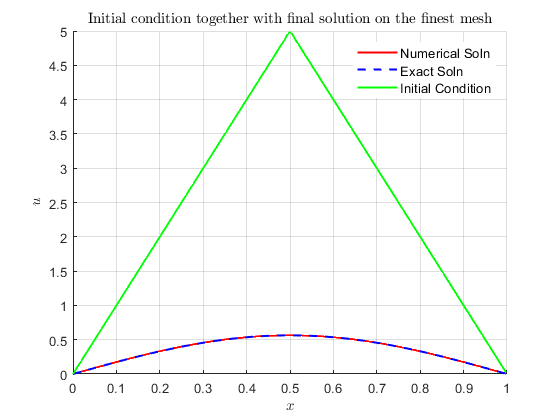

% Read data from Output.txt
data_2e = dlmread('Output.txt', '', 1, 0);
data_2e = sortrows(data_2e);
n = length(data_2e);
x_2e = data_2e([1:n-1], 1);
ic_2e = data_2e([1:n-1], 2);
u_2e = data_2e([1:n-1], 3);
e_2e = data_2e([1:n-1], 4);

figure (2)
hold on
numerical = plot(x_2e, u_2e, 'r-', 'LineWidth', 1.5);
exact = plot(x_2e, e_2e, 'b--', 'LineWidth', 1.5);
initial = plot(x_2e, ic_2e, 'g-', 'LineWidth', 1.5);

title('Initial condition together with final solution on the finest mesh', 'interpreter', 'latex', 'FontSize', 10); 
ylabel('$u$', 'interpreter', 'latex', 'FontSize', 10), xlabel('$x$', 'interpreter', 'latex', 'FontSize', 10);
set(gca,'FontSize', 10);
L = legend([numerical exact initial], 'Numerical Soln', 'Exact Soln', 'Initial Condition', 'Location', 'Northeast');
L.FontSize = 10;
grid on
hold off

## Question 2a

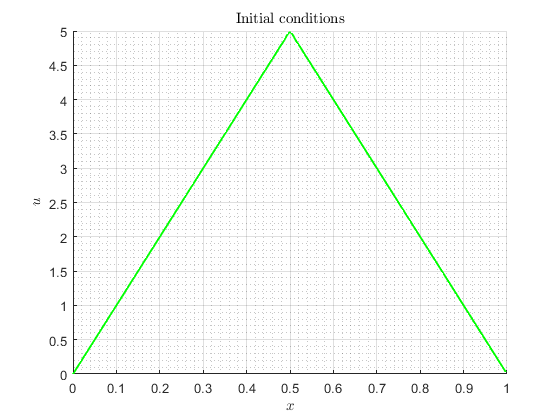

figure (3)
hold on
initial = plot(x_2e, ic_2e, 'g-', 'LineWidth', 1.5);

title('Initial conditions', 'interpreter', 'latex', 'FontSize', 10); 
ylabel('$u$', 'interpreter', 'latex', 'FontSize', 10), xlabel('$x$', 'interpreter', 'latex', 'FontSize', 10);
set(gca,'FontSize', 10);
grid minor
grid on
hold off

## Question 2d

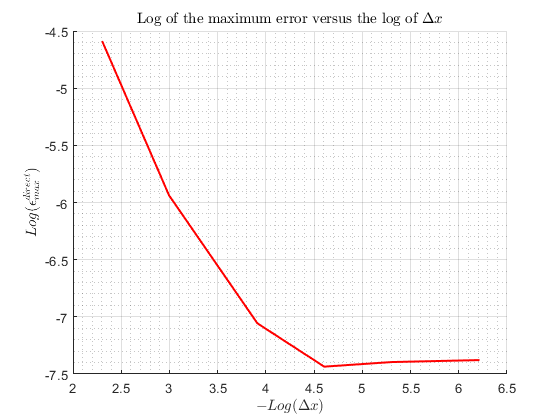

dx_2d = [0.1 0.05 0.02 0.01 0.005 0.002];
err_2d = [0.01016627 0.002638874 0.0008614371 0.00058978008 0.0006138547 0.0006247668];

figure (4)
hold on
maxeps_2d = plot(-log(dx_2d), log(err_2d), 'r-', 'LineWidth', 1.5);

title('Log of the maximum error versus the log of $\Delta x$', 'interpreter', 'latex', 'FontSize', 10); 
ylabel('$Log( \epsilon_{max}^{direct})$', 'interpreter', 'latex', 'FontSize', 10), xlabel('$-Log( \Delta x)$', 'interpreter', 'latex', 'FontSize', 10);
set(gca,'FontSize', 10);
grid minor
grid on
hold off